# Trabalho de EE-254 (Controle Preditivo): Parte 1

Considere o seguinte sistema de dois carros acoplados por uma mola:

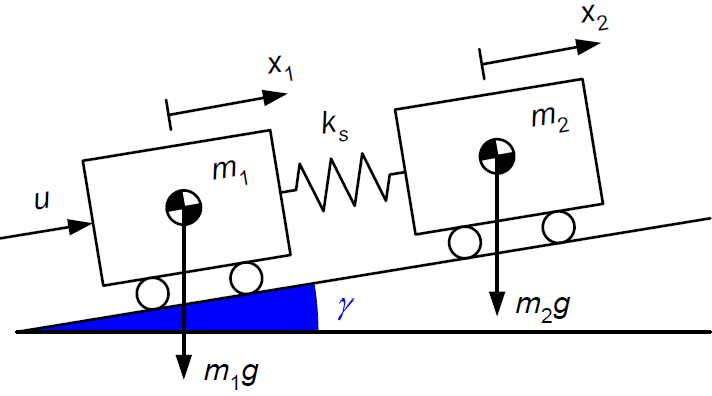

com deslocamentos $x_1$, $x_2$ definidos de modo que a mola esteja relaxada quando $x_1 = x_2$. O **ângulo de inclinação** $\gamma$ é constante, mas de **valor desconhecido**. 

A dinâmica deste sistema, a tempo contínuo, é descrita pelas seguintes equações:


$$m_1 \ddot{x}_1(t) = u(t) + k_s \big[\, x_2(t) - x_1(t) \,\big] - m_1 g \, \text{sen} \, \gamma$$



$$m_2 \ddot{x}_2(t) = - k_s \big[\, x_2(t) - x_1(t) \,\big] - m_2 g \, \text{sen} \, \gamma$$


que podem ser colocadas na forma 


$$\dot{x}(t) = A_c x(t) + B_c u(t) + E_c \bar{d}$$


com $x_3 = \dot{x}_1$, $x_4 = \dot{x}_2$, $\bar{d} = g \, \text{sen} \, \gamma$ e

$A_c =
\left[
  \begin{array}{cccc}
    0 & 0 & 1 & 0 \\[4pt]
    0 & 0 & 0 & 1 \\[4pt]
    -k_s/m_1 & k_s/m_1 & 0 & 0 \\[4pt]
    k_s/m_2 & -k_s/m_2 & 0 & 0 \\
  \end{array}
\right]$, $B_c =
\left[
  \begin{array}{c}
    0 \\[4pt]
    0 \\[4pt]
    1/m_1 \\[4pt]
    0 \\
  \end{array}
\right]$, $E_c =
\left[
  \begin{array}{c}
    0 \\[4pt]
    0 \\[4pt]
    -1 \\[4pt]
    -1 \\
  \end{array}
\right]$

Neste trabalho, serão adotados os seguintes valores para os parâmetros do modelo:

$m_1 = 5$ kg, $m_2 = 3$ kg, $k_s = 10$ N/m, $g = 9\text{,}8$ m/s${}^2$

que resultam nas matrizes $A_c$, $B_c$, $E_c$ definidas no código abaixo:

m1 = 5; m2 = 3; ks = 10; g = 9.8;
Ac = [0 0 1 0;
      0 0 0 1;
      -ks/m1 ks/m1 0 0;
      ks/m2 -ks/m2 0 0];
Bc = [0;0;1/m1;0];
Ec = [0;0;-1;-1];

A variável a ser controlada será o deslocamento do segundo carro, isto é, $y = x_2$. Essa é uma equação de saída da forma $y(t) = C x(t)$ com 

C = [0 1 0 0];


A tarefa de controle consiste em deslocar o segundo carro por uma distância de 1 m, com tempo de subida (10 % a 90 %) de até 6 s. Adicionalmente, deseja-se que a deformação da mola e o controle (ambos em módulo) não ultrapassem 0,05 m e 2 N, respectivamente, quando a inclinação for nula ($\gamma = 0$).

#### Item a (1,0 ponto)

Adotando um período de amostragem $T = 0\text{,}2$ s, discretize a equação de estado na forma


$$x(k+1) = A x(k) + B u(k) + E \bar{d}$$


considerando que o controle seja aplicado por meio de um segurador de ordem zero. 

T = 0.2; % sample
%angulo inclinação
x2=0.05;

dbar = g* sin(x2) % perturbação cte

dbar = 0.4898



% E=Ec * dbar %%%%%%%%%%%%%%%%%%%%%%%%% verify
Sysc = ss(Ac, Bc, [], []);
Sys=c2d(Sysc, T, 'zoh');

A=Sys.A

A =     0.9607    0.0393    0.1974    0.0026
    0.0655    0.9345    0.0044    0.1956
   -0.3859    0.3859    0.9607    0.0393
    0.6432   -0.6432    0.0655    0.9345


B=Sys.B

B =     0.0040
    0.0000
    0.0395
    0.0009



[~, E] =c2dm(Ac, Ec, [], [], T, 'zoh')

E =    -0.0200
   -0.0200
   -0.2000
   -0.2000



% Aexp = expm(Ac*T)
% Bexp = inv(Ac)*(expm(Ac*T) - eye(4)) * Bc %% verify


poles = eig(A) % autovalores sao as raizes de um polinomio caracteristico

poles =    0.8952 + 0.4456i
   0.8952 - 0.4456i
   1.0000 + 0.0000i
   1.0000 + 0.0000i


% or 
% poles = exp(eig(Ac)*T)

% positive poles = unstable



**Resultado esperado:**

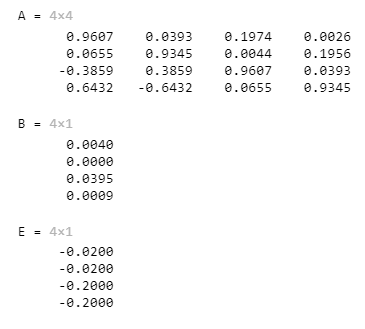

Desconsiderando inicialmente a presença da perturbação, vamos projetar uma lei de controle da forma


$$u(k) = -K (x(k) - \bar{x}) + \bar{u}$$


sendo $\bar{x}$, $\bar{u}$ os valores de equilíbrio desejados para o estado e o controle.

#### Item b (1,0 pontos) 

Determine $N_x$, $N_u$ de modo que $\bar{x} = N_x \bar{r}$ e $\bar{u} = N_u \bar{r}$, sendo $\bar{r}$ o valor de referência para a variável controlada $y$.

%aula 4
 
%aux = inv([A-eye(4) B; C 0])*[0; 0; 0; 1; 1];
%aux0 = inv([A - eye(4) B;C 0])

aux = inv([A - eye(4) B; C 0])*[E; 1]

aux =     0.7000
    1.0000
    0.0000
    0.0000
   -8.0000


aux = inv([A - eye(4) B; C 0])*[-E; 0]

aux =     0.3000
         0
    0.0000
   -0.0000
    8.0000


aux = inv([A - eye(4) B; C 0])*[0; 0; 0; 0; 1]

aux =     1.0000
    1.0000
    0.0000
    0.0000
    0.0000



Nx = aux(1:4)

Nx =     1.0000
    1.0000
    0.0000
    0.0000


Nu = aux(5)

Nu = 3.5567e-16


rbar=1e-1;
ubar=Nu*rbar % + M*dbar ;

ubar = 3.5567e-17

xbar=Nx*rbar % + Mx*dbar ;

xbar =     0.1000
    0.1000
    0.0000
    0.0000


**Resultado esperado:**

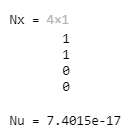

Constata-se, portanto, que $\bar{x}_1 = \bar{x}_2 = \bar{r}$, $\bar{x}_3 = \bar{x}_4 = 0$ e $\bar{u} = 0$ (a menos de imprecisão numérica), o que é consistente com a física do movimento do sistema.

Vamos projetar o ganho $K$ pelo método do regulador linear-quadrático, de modo a minimizar o custo


$$J = \sum_{k = 0}^{\infty} \Big[\, \mu_1(x_1(k) - \bar{x}_1)^2 + \mu_2(x_2(k) - \bar{x}_2)^2 + \mu_3x_3^2(k) + \mu_4x_4^2(k) + \mu_5(x_1(k) - x_2(k))^2 + \rho u^2(k) \, \Big]$$


sendo $\mu_1, \mu_2, \mu_3, \mu_4, \mu_5, \rho$ constantes positivas a serem ajustadas. Como $\bar{x}_3 = \bar{x}_4 = 0$ e $\bar{u} = 0$, o custo $J$ pode ser expresso, de forma equivalente, como


$$J = \sum_{k = 0}^{\infty} \Big[\, \|x(k) - \bar{x}\|^2_Q + \|u(k) - \bar{u}\|^2_R \, \Big]$$


com 

$Q =
\left[
  \begin{array}{cccc}
    \mu_1 + \mu_5 & - \mu_5 & 0 & 0 \\[4pt]
    -\mu_5 & \mu_2 + \mu_5 & 0 & 0 \\[4pt]
    0 & 0 & \mu_3 & 0 \\[4pt]
    0 & 0 & 0 & \mu_4 \\
  \end{array}
\right]$, $R = \rho$

#### Item c (1,0 pontos)

Considerando que a excursão das variáveis de estado e controle sejam tais que


$$|x_1 - \bar{x}_1|_{max} = |x_2 - \bar{x}_2|_{max} = 1 \text{ m}, |x_3|_{max} = |x_4|_{max} = (0,9 - 0,1) \text{m} / (6 \text{ s}), |x_1 - x_2|_{max} = 0,05 \text{ m}, |u|_{max} = {2} \text{ N}$$


utilize a regra de Bryson para escolher os pesos $Q$, $R$ e determine o ganho $K$do controlador.

% aula 5 - K cte (situação otima)
% erro -> 0

% proporcao distancia da mola

% regra bryson
% qii = 1/max mod(x_i)
% rjj=1/max mod(u_j)
q=1 % Q = Q_BAR and R = r * R_BAR

q = 1



x1 = 1

x1 = 1

x2 = 1

x2 = 1

x3_max = 0.8/6 % [m/s]

x3_max = 0.1333

x4_max = x3_max

x4_max = 0.1333

x1_x2_max = 0.05

x1_x2_max = 0.0500

u_max = 2 % rho

u_max = 2



u1 = 1/x1^2

u1 = 1

u2 = u1

u2 = 1

u3 = 1/(x3_max^2)

u3 = 56.2500

u4 = 1/(x4_max^2)

u4 = 56.2500

u5 = 1/(x1_x2_max^2) % spring noise affects u1 and u2

u5 = 400.0000

rho= 1/(u_max^2)

rho = 0.2500


R= rho

R = 0.2500

Q = [u1+u5 -u5 0 0; -u5 u2+u5 0 0;0 0 u3 0; 0 0 0 u4]

Q =   401.0000 -400.0000         0         0
 -400.0000  401.0000         0         0
         0         0   56.2500         0
         0         0         0   56.2500




[K, S, e] = lqr(A,B,Q,R)

K = 	1.0e+04 *

    0.0832    1.4944    0.0065    0.1385


S = 	1.0e+07 *

    0.0052    0.0689   -0.0000   -0.0014
    0.0689    2.9682   -0.0003   -0.0235
   -0.0000   -0.0003    0.0000    0.0004
   -0.0014   -0.0235    0.0004    0.0305


e =   -0.9304 + 0.4371i
  -0.9304 - 0.4371i
  -1.1099 + 0.0000i
  -1.0000 + 0.0000i


[K, S, e] = dlqr(A,B,Q,R)

K =    20.7514  -19.0366   18.1692   -3.5639


S = 	1.0e+03 *

    1.9620   -1.8686    0.2825    0.1975
   -1.8686    1.8604   -0.2636   -0.1436
    0.2825   -0.2636    0.1997   -0.0123
    0.1975   -0.1436   -0.0123    0.4798


e =    0.6690 + 0.3241i
   0.6690 - 0.3241i
   0.6831 + 0.0000i
   0.9736 + 0.0000i





%{

Q = diag()
K = place(A,B,poles)

eig(A-B*K)
poles = eig(A-B*K) % autovalores sao as raizes de um polinomio caracteristico

%}

%{
% controle nao deve ultrapassar  0.05 m e 2 N quando inclinação for = 0

eigc12 = roots([1 2*xi*wn wn^2])
eigc34 = -6*xi*wn*[1;1];
eigc = [eigc12; eigc34]

eigd=exp(eigc*T)

g=place(A', B, poles)
K_siso = acker(A,B, eigd)
eig(A-B*K_siso)

Q = C'*C;
R = 1;
K = lqr(A,B,Q,R)
Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D]
%}


**Resultado esperado:**

#### Item d (2,0 pontos)

Simule o sistema em malha fechada, considerando inclinação nula ($\gamma = 0$) e empregando passo de simulação 10 vezes menor que o período de amostragem. Apresente gráficos da saída $y(t)$, da deformação da mola $x_1(t) - x_2(t)$e também do controle $u(t)$, do instante $t = 0$ ao instante $t = 20$ s. Determine o tempo de subida (10 % a 90 %) de forma computacional (isto é, por meio de código e não por inspeção visual dos gráficos).

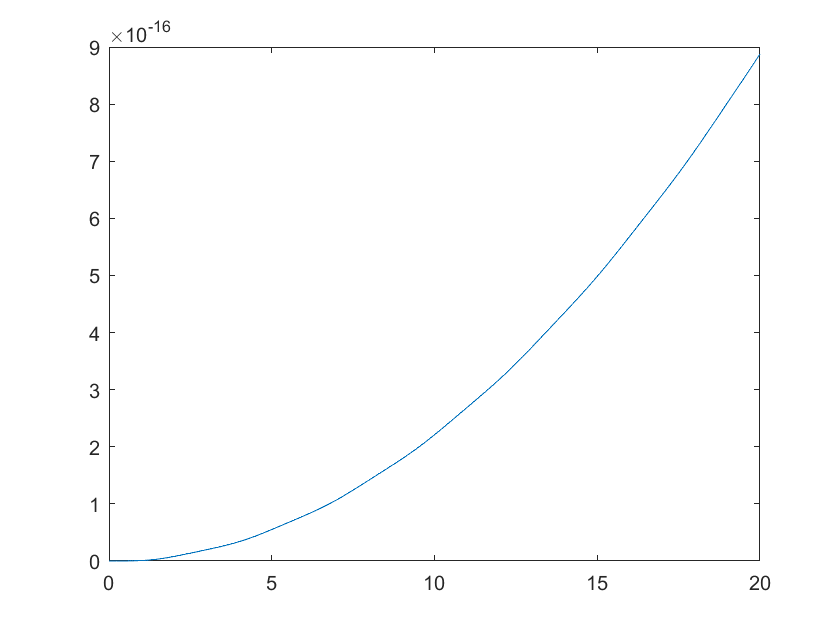

% aula 3 - usar lsim ???
% Sugere-se usar o comando abaixo para desabilitar mensagens sobre o início da simulação em instante não nulo

warning off 
xi=0.69; % natural frequency dynamics
wn=1.8/6 ; % 6 seconds 
nRow =20;

Ts=T/10;
t=[0:Ts:nRow];


sys = ss(Ac,Bc,C,[0]);
y = step(sys,t)*ubar;


figure()
% plot of the open-loop system for step response
plot(t,y)


Pc = [B A*B]

Pc =     0.0040    0.0116
    0.0000    0.0006
    0.0395    0.0364
    0.0009    0.0059


ctrb(A,B)

ans =     0.0040    0.0116    0.0184    0.0239
    0.0000    0.0006    0.0027    0.0068
    0.0395    0.0364    0.0310    0.0243
    0.0009    0.0059    0.0150    0.0261


eig(Pc*Pc')

ans =    -0.0000
    0.0000
    0.0000
    0.0030



% eigenvalues of the open-loop system 
J_openloop =eig(A)

J_openloop =    0.8952 + 0.4456i
   0.8952 - 0.4456i
   1.0000 + 0.0000i
   1.0000 + 0.0000i





% ---------- Resposta à entrada U do sistema projetado ----------
dt = T/10;
nt = (T/dt) + 1;

%U = repmat(u{k}',nt,1); % uma matriz de dimensoes nt × p 
% com uma linha correspondendo a cada instante de tempo.

sys = ss(Ac,Bc,C,0);
% set initial condition
x{1}=[0;0;0;0]; 
unlbar = [0;2];
trec = 0; xrec = x{1}'; yrec = 0;

u = cell(nRow,1) ;

for k = 1:nRow
    u{k} = ubar - K*(x{k} - xbar);
    t = linspace((k-1)*T,k*T,nt);
    U = repmat(u{k}',nt,1);
    [yout,tout,xout] = lsim(sys,U,t,x{k});
    trec = [trec;tout(2:end)];
    xrec = [xrec;xout(2:end,:)];
    yrec = [yrec;yout(2:end)];
    
    x{k+1} = xrec(end,:)';
end

i1 = min(find(yrec >= 0.1));
i2 = min(find(yrec >= 0.9))
];
tr = t2 - t1

% compute the eigenvalues of the closed loop system 
J=eig(A-B*K)


% ---------------------------------------------------------------------
k0=acker(A,B,J) 
k1=place(A,B,J) 

Ac = [(A-B*K)];
Bc = [B];
Cc = [C'];
Dc = [E];

k1 = k1(1);

b2k=B*k1;

% ---------- Resposta ao degrau unitário mais a etrada em rampa unitaria do sistema projetado ----------

% lsim : Obtenção da resposta a uma entrada arbitrária
%[y,t,x] = lsim(sys_cl,r,t); 

r=1+t;% entrada em degrau de valor 1 mais a etrada em rampa unitaria
%pagina 706
figure()
yout = lsim(Ac, b2k(:,1), eye(4), zeros(4,1), r, t);
plot(t,r,'-',t,yout,'o')
grid
title('Resposta à Entrada r(t) = 1+t Obtida com o Uso do Comando "lsim"')
xlabel('t (s)')
ylabel('Entrada e Saída do sistema')



% ---------- Resposta ao degrau unitário do sistema projetado ----------

%sys_cl = ss(Ac,Bc,Cc,Dc)



sys = ss(Ac, eye(4),eye(4),eye(4));

%sys = ss([A-B*K B*K; zeros(2,2) A-K*C],eye(4),eye(4),eye(4));

z = initial(sys,[1;0;0;0],t);

x1=[1 0 0 0]*z';
x2=[0 1 0 0]*z';
e1=[0 0 1 0]*z';
e2=[0 0 0 1]*z';
figure()
subplot(2,2,1); plot(t,x1 ),grid
title('Resposta à condição inicial')
ylabel('variável de estado x1')
subplot(2,2,2); plot(t,x2),grid
title('Resposta à condição inicial')
ylabel('variável de estado x2')
subplot(2,2,3); plot(t,e1),grid
xlabel('t (s)'), ylabel('variável de estado de erro e1')
subplot(2,2,4); plot(t,e2),grid
xlabel('t (s)'), ylabel('variável de estado de erro e2')
%{
plot(t,y(:,1),'--',t,y(:,2),'-',t,y(:,3),'-.'), grid
legend('\itu','\itx','\itq')
set(gca,'FontName','Times','FontSize',14)
%}

%[AX,H1,H2] = plot(t, y(:,1), t,y(:,2),'plot'); 

%set(get(AX(1),'Ylabel'),'String','position (m)') 

%set(get(AX(2),'Ylabel'),'String','velocity (m/s)')

k1 = K(1); k2 = K(2); k3 = K(3);
% ***** Defina matriz de estado, matriz de controle, matriz de saída
% e matriz de transmissão direta dos sistemas projetados como
% BB, CC, e DD *****
AA = A - B*K;
BB = B*k1;
CC = C;
DD = E;
figure()

% ---------- Resposta ao degrau unitário do sistema projetado ----------

[y,x,t] = step (AA,BB,CC,1,t);
plot(t,x)
grid
title('Curvas de resposta x1, x2, x3, x4, versus t')
xlabel('t (s)')
ylabel('x1,x2,x3,x4')
text(2.6,1.35,'x1')


text(1.2,1.5,'x2')
text(0.6,3.5,'x3')






figure(2)

% sis se deslocando na horizontal
for k = 1:20
    u{k} = ubar -K*(x{k} - xbar) ;
    x{k+1} = A*x{k} + B*u{k} ; %+ E*dbar ;
    % unl{k} = u{k} + unlbar;
    %X = [x{1,:}]; hold on
    %plot(X(1,:),(X(2,:),k,'b-o'); 
end


y=X(4,:);


figure(3)


%simulate the closed loop system

y=lsim(Acl, b2k(:,2), eye(4), zeros(4,1), thetac, t);


%{

plot(X(1,:),tr)
hold on
plot(X(2,:),tr)

for i = 1:20
    plot(u(i,:))
end
hold off
xlabel('Iterações')
ylabel('Sinal de controle: u(rad/s)')
plot(err)
xlabel('Iterações')
ylabel('Norma do erro: |e|')
box off
%}


%% define the desired state 
xd=[0; 0; 0; 0];
%final simulation time 
tFinal=30;
time_total=0:0.1:tFinal;
%% compute ud
  
% set initial condition
x0=1*randn(4,1);

ud=-inv(B'*B)*B'*A*xd
closed_loop_input=[xd(1)*ones(size(time_total));
                    xd(2)*ones(size(time_total));
                    xd(3)*ones(size(time_total));
                    xd(4)*ones(size(time_total))];
%{
 % closed loop matrix 
Acl= A-B*K;
Bcl=-Acl;
D=[0];
sysSSClosedLoop=ss(Acl,Bcl,C,D)


[output_closed_loop,time_closed_loop,state_closed_loop] = lsim(sysSSClosedLoop,closed_loop_input,time_total,x0); 

figure(2)
%plot(output_closed_loop(:,1),'k')
%hold on 
%plot(output_closed_loop(:,2),'r')
xlabel('Time [s]')
ylabel('Position and velocity')
plot(time_closed_loop,state_closed_loop(:,1),'m')
hold on
plot(time_closed_loop,state_closed_loop(:,2),'b')
hold on
legend('Position-Constant Input ','Velocity-Constant Input','Position-Closed Loop ','Velocity-Closed Loop')
grid
                    
%}


#### Item e (1,0 pontos)

Refaça o item (d), reajustando os pesos $Q, R$ de forma conveniente para atender as especificações de tempo de subida, deformação da mola e magnitude do controle.

% tentativa eerro - Insira seu código aqui
Q=[100 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];
r=0.01

% K = matriz ganho de retroação
% P = solução P da equação Riccati
% polos MF (autovalores de A-BK)
[K,P,E] = dlqr(A,B,Q,R)

AA=A-B*K; % com realimentação

**Observação:** Caso não tenha sido possível completar o item (d), sugere-se usar o ganho abaixo, que atende as especificações para a tarefa de controle.

#### 

#### Item f (2,0 pontos)

Supondo que as variáveis de estado $x_1$, $x_2$, $x_3$, $x_4$ sejam todas medidas, projete um observador de estados *deadbeat* de modo a estimar o ângulo de inclinação $\gamma$.

% dead beat- avisar ser ficar diferente
eig_des = [0 0];
K = acker(A,B,eig_des)


% Projeto do observador deadbeat
E = B;
Achi = [A E;zeros(2,4) eye(4)];
Bchi = [B;zeros(4,2)];
H = eye(4);
Hchi = [H zeros(4,2)];
eig_des = [0:5]*1e-2;
L = (place(Achi',Hchi',eig_des))'
M = inv(Achi)*L
eig(Achi - M*Hchi*Achi)



**Observação: **O observador será implementado fazendo uso do seguinte estado aumentado: 


$$\chi(k) =
\left[
  \begin{array}{c}
    x(k) \\[4pt]
    d(k) \\
  \end{array}
\right]$$


e as seguintes equações:


$$\chi(k|k) = \chi(k|k-1) + M\big[z(k) - z(k|k-1)\big]$$



$$z(k|k-1) = H_\chi \chi(k|k-1)$$



$$\chi(k+1|k) = A_\chi \chi(k|k) + B_\chi u(k)$$


com $z(k) = x(k)$e matrizes $A_\chi$, $B_\chi$, $H_\chi$ definidas de forma conveniente. A menos de imprecisão numérica, espera-se que seja obtida a seguinte matriz de ganho $M$:

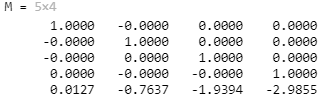

#### Item g (2,0 pontos) 

Utilizando o controlador sintonizado no item (e) e o observador projetado no item (f), refaça a simulação com inclinação $\gamma = 0,5^\circ$. Apresente gráficos da saída $y(t)$, da deformação da mola $x_1(t) - x_2(t)$, da estimativa da perturbação $\bar{d}(k|k)$ e também do controle $u(t)$, do instante $t = 0$ ao instante $t = 20$ s. Espera-se que a saída $y = x_2$ convirja assintoticamente para o valor de referência, sem erro de regime estacionário. Neste caso, a deformação da mola tende a ser maior em comparação com o item (e), devido à presença da perturbação.

% deformação fica maior - lsim
% sis se deslocando 0.5 graus

gamma = 0.5; %graus
dbar = g*sind(gamma);
x{1}=[0;0;0;0];

for k = 1:20
    u{k} = ubar -K*(x{k} - xbar) ;
    x{k+1} = A*x{k} + B*u{k} + E*dbar ;
end


Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.